7 e 8 exame normal 22/23

%S1 - cone
clear 
n = 50

n = 50

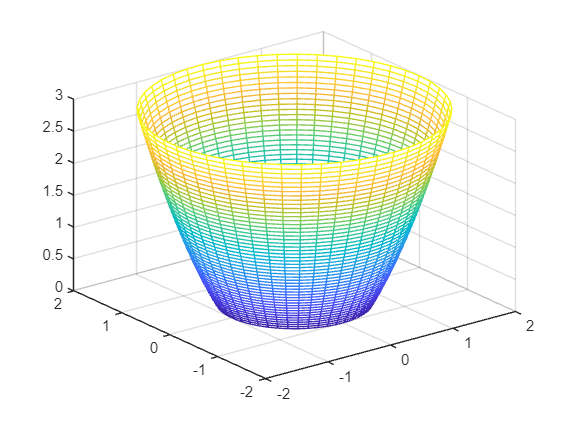

%passo 01 - grelha de pontos das variaveis independentes
theta = linspace(0,2*pi,n);
rho = linspace(1,2,n);

[theta,rho] = meshgrid(theta,rho);

%passo 02 - declarar e definir a var. dependente

z = rho.^2-1;

%passo 03 - converter coordenadas cilindricas para cartesianas

[xS1,yS1,zS1] = pol2cart(theta,rho,z);

%passo 04 - representação da superfície

mesh(xS1,yS1,zS1);

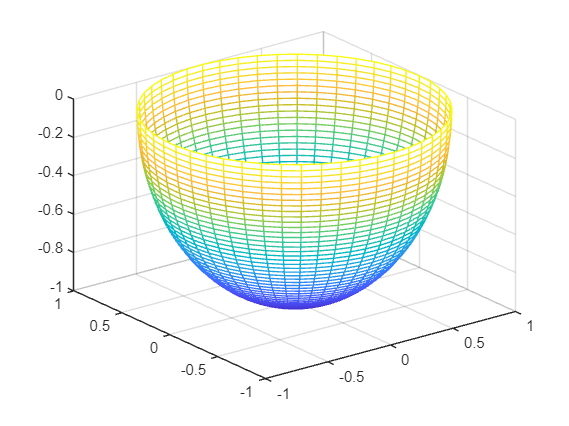

%S2 - calote esferica

%passo 01 - grelha de pontos das variaveis independentes
theta = linspace(0,2*pi,n);
phi = linspace(-pi/2,0,n);

[theta,phi] = meshgrid(theta,phi);

%passo 02 - declarar e definir a var. dependente

r = 1;

%passo 03 - converter coordenadas cilindricas para cartesianas

[xS2,yS2,zS2] = sph2cart(theta,phi,r);

%passo 04 - representação da superfície

mesh(xS2,yS2,zS2);



%mesh(xS1,yS1,zS1)
%hold on
%mesh(xS2,yS2,zS2)
%hold off
%axis equal


%S3 

%passo 01 - grelha de pontos das variaveis independentes
theta = linspace(0,2*pi,n);
rho = linspace(0,2,n);

[theta,rho] = meshgrid(theta,rho);

%passo 02 - declarar e definir a var. dependente

z  = -rho - 1;

%passo 03 - converter coordenadas cilindricas para cartesianas

[xS3,yS3,zS3] = pol2cart(theta,rho,r);

%passo 04 - representação da superfície

%mesh(xS3,yS3,zS3);





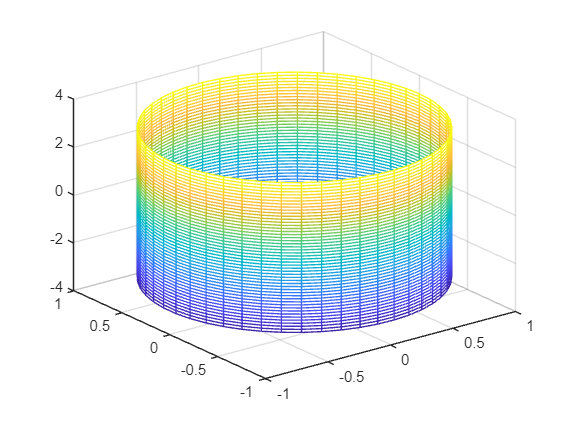

%s4
%passo 01 - grelha de pontos das variaveis independentes
theta = linspace(0,2*pi,n);
z = linspace(3.25,-3,n);

[theta,z] = meshgrid(theta,z);

%passo 02 - declarar e definir a var. dependente

rho =  1;

%passo 03 - converter coordenadas cilindricas para cartesianas

[xS4,yS4,zS4] = pol2cart(theta,rho,z);

%passo 04 - representação da superfície

mesh(xS4,yS4,zS4);

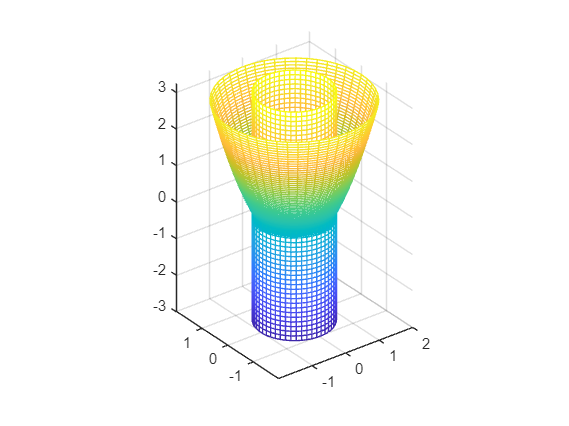


mesh(xS1,yS1,zS1)
hold on
mesh(xS2,yS2,zS2)
%mesh(xS3,yS3,zS3)
mesh(xS4,yS4,zS4)
hold off
axis equal



%Volumes
VS2 = 1/2*4/3*pi*r^3

VS2 = 2.0944

%VS1 = int(int(int(r*rho,z,rho^2-1,3),theta,0,2*pi),rho,0)
%VS11 = int(int(int(r*rho,z,rho^2-1,0),theta,0,2*pi),rho,0)

